# Surrogate Model-Based Optimization

## Goals

- **Introduce Surrogate Model-Based Optimization:** Define the framework of surrogate model-based optimization and illustrate how it offers a systematic approach to formulating and solving optimization problems using surrogate models.

- **Showcase Key Benefits:** Surrogate model-based optimization provides many advantages over traditional optimization methods. This optimization framework avoids common pitfalls by leveraging surrogate models and their structure. 

- **Performance Evaluation:** Demonstrate the efficiency and reliability of surrogate model-based optimization in providing timely and consistent solutions, underlining its capacity to deliver results rapidly and robustly.

## High-Level Highlights

The surrogate model-based optimization framework leverages the speed and structure of surrogate models to provide quick and robust solutions to engineering optimization problems. The table from one example highlights the significant differences in computation effort required for optimization while using surrogate and physics-based models. Complex optimization algorithms require many function evaluations, and using physics-based simulators to service these evaluation requests results in a considerable computation effort. Surrogate models remove this bottleneck by providing optimization algorithms with quick and accurate function evaluations.    

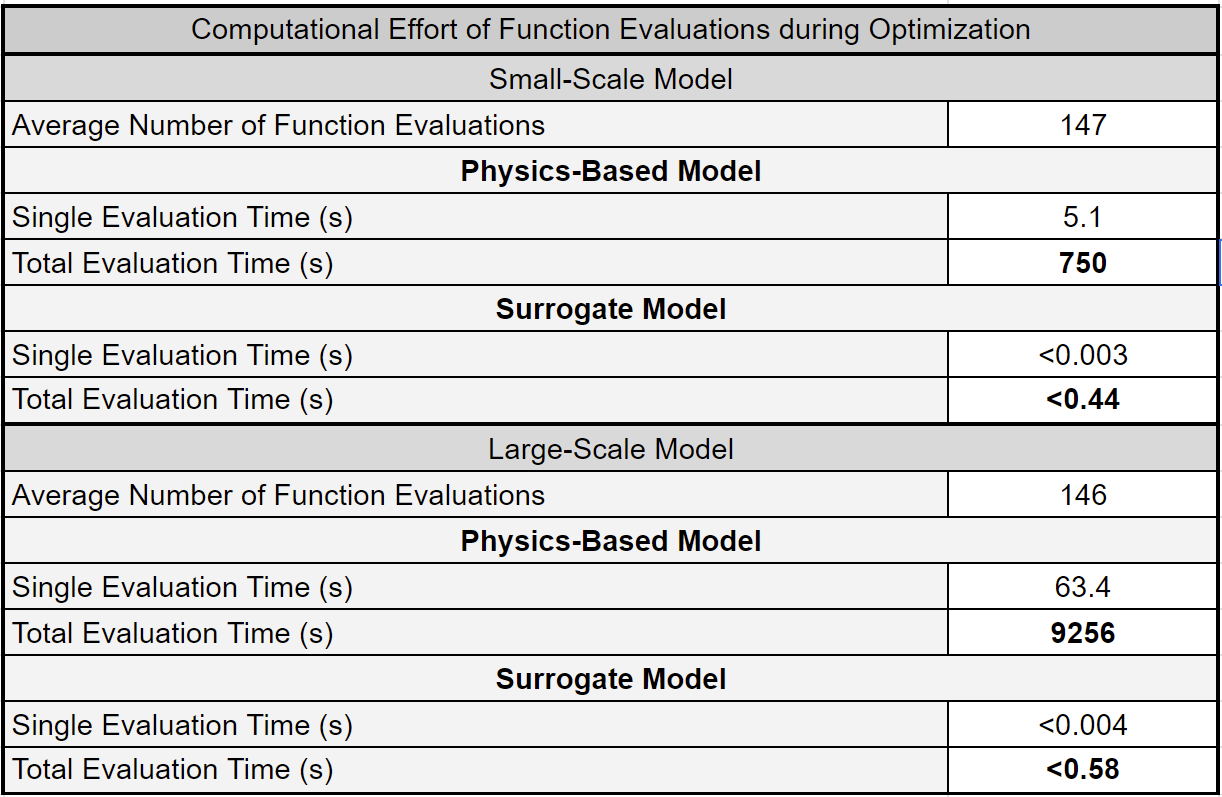

## General Optimization 

In the most general sense, mathematical optimization is the search for the "best x" given an objective function and, in most engineering applications, a set of constraints. Formally, the optimization problem is described as follows:


$$$$ \max_x{f(x)}\ \text{subject to} \ g(x)\leq0,$$$$


where the goal is to find the value of $x$ that results in the largest value of the objective, $f()$, while still adhering to the constraint(s), $g(
)
$. If we now cast the problem in the context of physics-based simulation, we can think of the function and constraints as functions of the outputs of the simulator and $x$ as the inputs to the simulator. In this context:


$$$$ \max_x{f(\text{simulator}(x))}\ \text{subject to} \ g(\text{simulation}(x))\leq0,$$$$


where, in a slight abuse of notation, $\text{simulator()}$ represents the physics-based simulation (i.e., takes in an input $x$ and returns some simulated outputs). While this notation deviates slightly from traditional mathematical conventions, it underscores the necessity of executing the simulator to evaluate the objective or constraint functions. For the water pumping networks we introduced in the Basics of Surrogate Model Creation, we describe the elements of the optimization problem as follows:


$$\text{x: pumping speeds,}\\
\text{simulator(): returns flowrates and pumping powers,}\\
\text{f(): collector flowrate,}\\
\text{g(), limit on total pumping power.}
$$


Therefore, the goal is to maximize the flow rate at the collector without exceeding the total power drawn by the system's pumps. This optimization problem is just one example of the many that can be formulated for water-pumping networks.

Mathematical optimization underpins most of engineering. The typical engineering trade-offs are often resolved via optimization. However, optimization is very computationally costly. Most optimization algorithms require many evaluations of the objective and constraint functions. In the context of physics-based simulation, this means executing the simulator repeatedly, and due to the nature of these algorithms, these executions occur in series. Moreover, this costly endeavor may only result in a "local" maximum, an $x$ that is better than those around it but not the absolute best. However, optimizing becomes much more attractive if we replace executing the physics-based model with a much less costly surrogate model. 

## Surrogate Model-Based Optimization 

Suppose a surrogate model is generated (with small prediction errors). In that case, the physics-based simulation optimization problem can be reformulated as follows:


$$$$ \max_x{f(\text{surrogate}(x))}\ \text{subject to} \ g(\text{surrogate}(x))\leq0.$$$$


The optimization problem is solved quicker since $\text{surrogate}(x)$ is evaluated much faster than $\text{simulator}(x)$. Furthermore, if the prediction errors are small (or insignificant), the solution should closely match one obtained with a physics-based simulator. 

[1] and [2] describe alternative formulations of surrogate model-based optimization. All three formulations use surrogate models' increased speed to obtain optimized answers much quicker. 

### Surrogate Construction and Optimization

Note that the inputs and outputs of the surrogate models will inform the set of possible optimization problems. The functions $f()$ and $g()$ can only be functions of the surrogate's inputs or outputs, and optimized inputs,$x$, must be a subset of the inputs to the surrogate. In the water-pumping networks example, we cannot, for example, have a constraint on a fluid's temperature since the surrogate model does not predict fluid temperature. Ideally, the optimization problem formulation should occur before constructing the surrogate.

### Decision and Fixed Variables

Not all of the inputs to the surrogates need to be optimized. Some may remain fixed during the optimization process. We labeled these inputs as "fixed variables." For example, suppose we create a surrogate model of a building heating system. Undoubtedly, the ambient temperature will be a surrogate input since it is an essential variable in determining the system's behavior. However, we should not optimize ambient temperature since we have no direct control of this variable. Nevertheless, the ambient temperature will affect any optimization done on this system. Therefore, we introduce a final iteration of the optimization problem formulation:


$$\ \text{given p} \  \max_{x_{\text{decision}}}{f(\text{surrogate}(x_{\text{decision}},x_{\text{fixed}}))}\ \text{subject to} \ g(\text{surrogate}(x_{\text{decision}},x_{\text{fixed}}))\leq0 \ \text{and} \ x_{\text{fixed}} = p.

$$


where $p
$ are the values of the fixed variables. The union of $x_{\text{decision}}$ and $x_{\text{fixed}}$ must equal the complete input set of the surrogate model. An optimization problem set up with fixed variables is given [3]. 

## Examples

Two examples of optimization problems are described and solved. We leveraged the framework's speed to execute the underlying optimization algorithm several times. Each execution is seeded with a random initial guess to provide a robust final answer (we output the best result). In practice, executions can be conducted in parallel to achieve quicker results. 

### Example 1: Maximize Collector Flowrate with Limited Power

In this example, we maximize the collector's flow rate and limit the pumps' total power draw. We also optimize the pump speeds, while the pressures at the sources and collector are assumed to be fixed variables.

Click on the button below to run a randomly selected optimization scenario. An outputted plot compares the optimized operating points at different power limits with a point cloud generated via the Monte Carlo method [4]. The optimized operating points provide the best achievable flowrate at different power limits. 

 
x = rand(5,1).*[0.5;1;1;1;1] + [1;0.5;0.5;0.5;0.5];

disp('Fixed Variables:')

Fixed Variables:


disp(['Pressure Collector (atm): ' num2str(x(1),'%.2f')])

Pressure Collector (atm): 1.21


disp(['Source 1-4 Pressures (atm): ' num2str(x(2),'%.2f') ', '...
                                    num2str(x(3),'%.2f') ', '...
                                    num2str(x(4),'%.2f') ', '...
                                    num2str(x(5),'%.2f')])

Source 1-4 Pressures (atm): 1.42, 0.61, 1.07, 0.74


Optimization beginning....
Optimization with a power limit of 1690(W) is complete.
15 out of 15 attempts were successful.
Optimization with a power limit of 1860(W) is complete.
15 out of 15 attempts were successful.
Optimization with a power limit of 2030(W) is complete.
15 out of 15 attempts were successful.
Optimization with a power limit of 2200(W) is complete.
15 out of 15 attempts were successful.
Optimization with a power limit of 2370(W) is complete.
15 out of 15 attempts were successful.
Total number of function evaluations: 9649
Average number of function evaluations in 75 optimizations: 128.6533


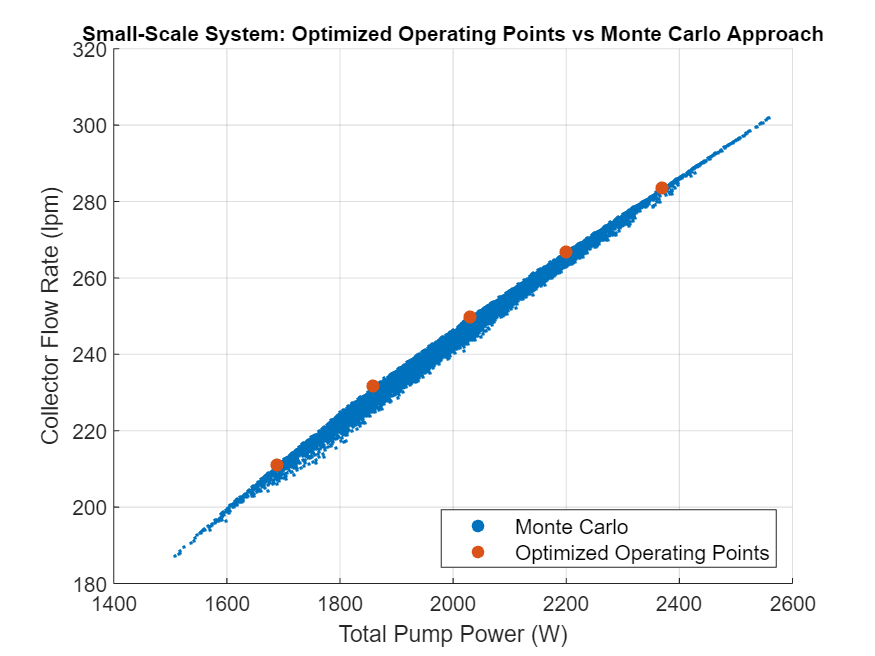


fixedVariables.collector_pressure = x(1);
fixedVariables.source_pressure_1 = x(2);
fixedVariables.source_pressure_2 = x(3);
fixedVariables.source_pressure_3 = x(4);
fixedVariables.source_pressure_4 = x(5);

addpath("./Example 1/")
example1_optimizaiton(fixedVariables);

pause(1)

We execute the same exercise with the large-scale system. Fixed variables are not displayed but are randomly sampled with each click on the button. Again, the optimized operating points provide the best achievable flow rate at different power limits. Due to the problem's dimension, the Monte Carlo approach is noticeably worse. 

Optimization beginning....
Optimization with a power limit of 16070(W) is complete.
15 out of 15 attempts were successful.
Optimization with a power limit of 16440(W) is complete.
15 out of 15 attempts were successful.
Optimization with a power limit of 16810(W) is complete.
15 out of 15 attempts were successful.
Optimization with a power limit of 17180(W) is complete.
15 out of 15 attempts were successful.
Optimization with a power limit of 17550(W) is complete.
15 out of 15 attempts were successful.
Total number of function evaluations: 11613
Average number of function evaluations in 75 optimizations: 154.84


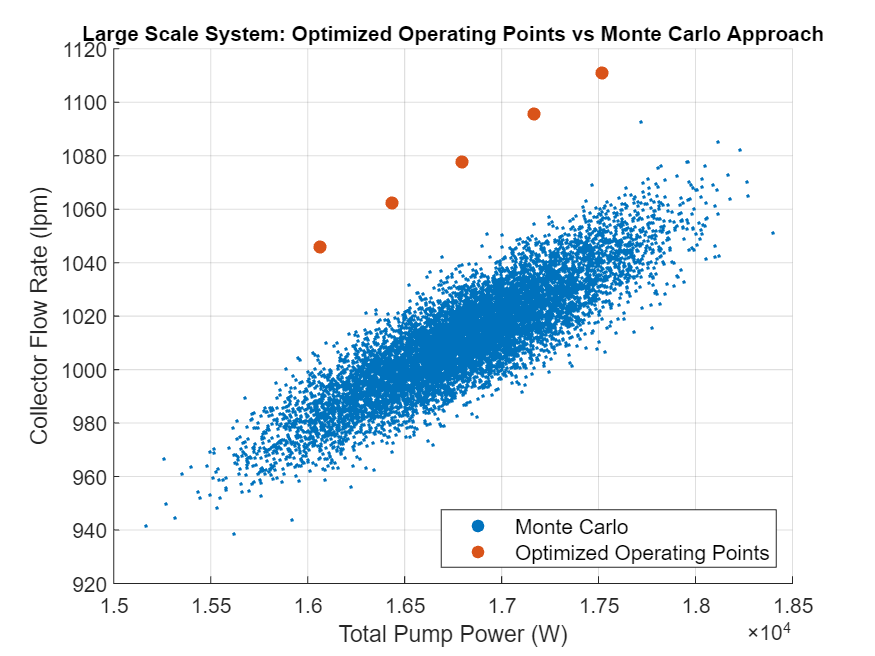

 
example1_largescale_optimizaiton();

pause(1)

The MLP surrogate models give the optimization algorithm access to quick function evaluations. The table below highlights how surrogate models eliminate major bottlenecks in optimization algorithms. Furthermore, physics-based models become largely impractical as the optimization problem grows in complexity and dimension. In contrast, surrogate model-based optimization remains feasible and responsive.

### Example 2: Maximize Profit with Limited Capacity 

We now consider the case in which an organization obtains a profit for transporting water from a source to the collector. The problem is made interesting by assuming each line incurs a different profit per liter of water transported, and there is a limit on the amount of water the collector can receive. The pump speeds and collector pressures are optimized, while the pressures at the sources are assumed to be fixed variables. 

Click on the button below to run a randomly selected optimization scenario. An outputted plot compares the optimized profit at different flow limits with a point cloud generated via the Monte Carlo method [4]. The optimized operating points provide the best achievable profits at different collector flow rates. 

 
x = rand(5,1).*[0.5;1;1;1;1] + [1;0.5;0.5;0.5;0.5];

disp('Fixed Variables:')

Fixed Variables:


disp(['Pressure Collector (atm): ' num2str(x(1),'%.2f')])

Pressure Collector (atm): 1.30


disp(['Source 1-4 Pressures (atm): ' num2str(x(2),'%.2f') ', '...
                                    num2str(x(3),'%.2f') ', '...
                                    num2str(x(4),'%.2f') ', '...
                                    num2str(x(5),'%.2f')])

Source 1-4 Pressures (atm): 1.26, 1.48, 1.40, 0.52



fixedVariables.collector_pressure = x(1);
fixedVariables.source_pressure_1 = x(2);
fixedVariables.source_pressure_2 = x(3);
fixedVariables.source_pressure_3 = x(4);
fixedVariables.source_pressure_4 = x(5);

p = rand(4,1);
disp('Prices:')

Prices:


disp(['Line 1-4 Prices ($/lpm): ' num2str(p(1),'%.2f') ', '...
                                    num2str(p(2),'%.2f') ', '...
                                    num2str(p(3),'%.2f') ', '...
                                    num2str(p(4),'%.2f')])

Line 1-4 Prices ($/lpm): 0.94, 0.90, 0.55, 0.01


Optimization beginning....
Optimization with a collector flow limit of 210(lpm) is complete.
15 out of 15 attempts were successful.
Optimization with a collector flow limit of 235(lpm) is complete.
15 out of 15 attempts were successful.
Optimization with a collector flow limit of 260(lpm) is complete.
15 out of 15 attempts were successful.
Optimization with a collector flow limit of 285(lpm) is complete.
15 out of 15 attempts were successful.
Optimization with a collector flow limit of 310(lpm) is complete.
15 out of 15 attempts were successful.
Total number of function evaluations: 2867
Average number of function evaluations in 75 optimizations: 38.2267


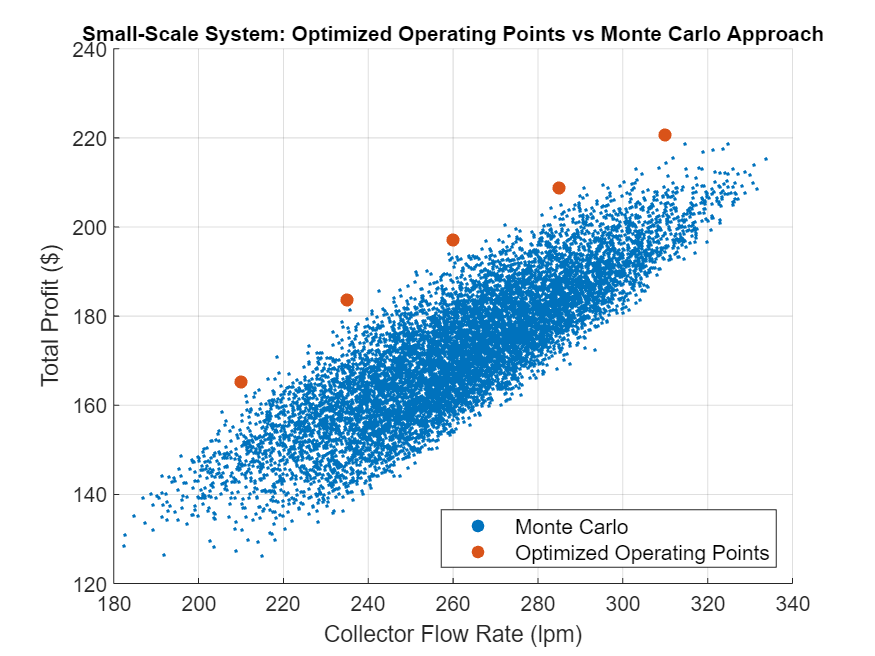



prices.line_1 = p(1);
prices.line_2 = p(2);
prices.line_3 = p(3);
prices.line_4 = p(4);
addpath("./Example 2/")
example2_optimizaiton(fixedVariables, prices);

pause(1)

We execute the same exercise with the large-scale system. Fixed variables and prices are not displayed but are randomly sampled with each click on the button. Again, the optimized operating points provide the best achievable profit at different flow rate limits. Due to the problem's dimension, the Monte Carlo approach is noticeably worse. 

Optimization beginning....
Optimization with a collector flow limit of 800(lpm) is complete.
15 out of 15 attempts were successful.
Optimization with a collector flow limit of 852.5(lpm) is complete.
15 out of 15 attempts were successful.
Optimization with a collector flow limit of 905(lpm) is complete.
15 out of 15 attempts were successful.
Optimization with a collector flow limit of 957.5(lpm) is complete.
15 out of 15 attempts were successful.
Optimization with a collector flow limit of 1010(lpm) is complete.
15 out of 15 attempts were successful.
Total number of function evaluations: 14258
Average number of function evaluations in 75 optimizations: 190.1067


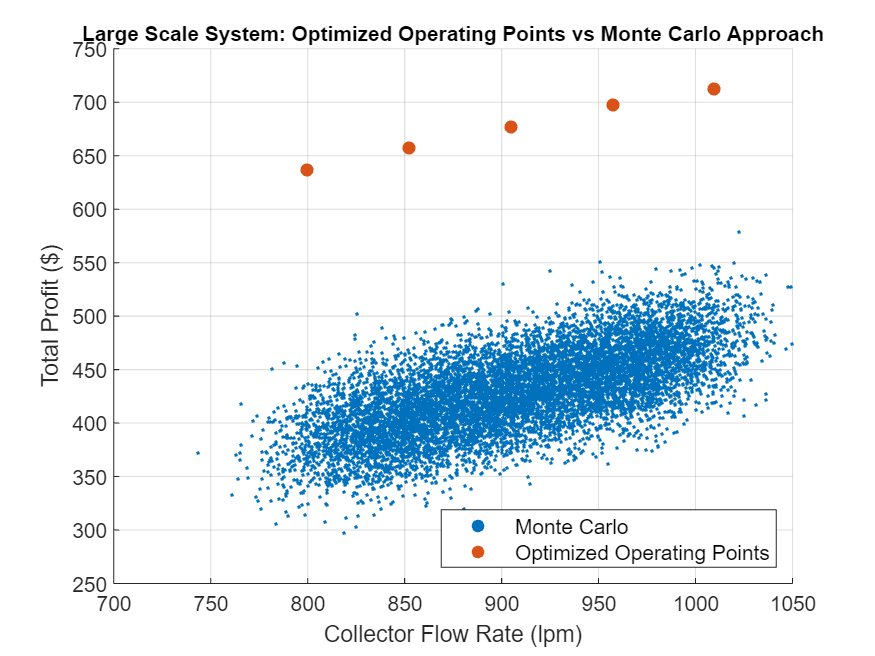

 
example2_largescale_optimizaiton();

## Summary

We can leverage surrogate models to perform fast and robust optimization. The MLP surrogate models give the optimization algorithm access to quick function evaluations. The article presented two examples of an optimization problem solved using small and large-scale water-pumping network systems. Finally, optimization underpins most engineering problems, and many more applications (i.e., parameter estimation, controller tuning, sensitivity analysis) share the same or very similar formulations. 

## References

- [FOQUS Surrogate Model-Based Optimizer](https://foqus.readthedocs.io/en/latest/chapt_sm_optimizer/reference/SM_based_optimizer_introduction.html)

- [Surrogate model-based optimisation of a batch distillation process](https://www.sciencedirect.com/science/article/pii/S0263876223001399)

- [FOQUS Optimization Problem Set Up](https://foqus.readthedocs.io/en/latest/chapt_opt/reference/optimization.html#problem-set-up)

- [Example comparing Monte Carlo vs Numerical Optimization](https://medium.com/@aaron_delarosa/portfolio-optimization-and-var-using-monte-carlo-simulation-and-scipy-optimize-b570f95673c3)